# Train a Q-Learning Agent for the Dice Game

## Define the environment

Discrete states and actions. 

Observation : The variable capturing the state of the game. What values does it take (What is the observation space)? 

Action: What are the actions an agent takes? What are the set of actions?

obsInfo = rlFiniteSetSpec(0:20);
actInfo = rlFiniteSetSpec(1:5);

slEnv = rlSimulinkEnv("targetDice","targetDice/RL die chooser",obsInfo,actInfo);
slEnv.ResetFcn = @randomizeseed;

## Define the agent

Create a Q-table to represent a Q-value function.

T = rlTable(obsInfo,actInfo);
QT = rlQValueFunction(T,obsInfo,actInfo);

Create a Q-learning agent. Use $\gamma$= 1 (all rewards equally weighted).

learnopts = rlOptimizerOptions("LearnRate",0.005,"GradientThreshold",10);
opts = rlQAgentOptions("DiscountFactor",1,"CriticOptimizerOptions",learnopts);
agent = rlQAgent(QT,opts);

## Train the agent

Check to train agent from scratch.

dotraining = true;

Train agent or load pretrained agent from file.

Training target is an average episode reward of -3. This can happen by luck on the first episode. If so, rerun to try training again.

if dotraining
    opts = rlTrainingOptions("MaxStepsPerEpisode",20, ...
        "ScoreAveragingWindowLength",100, ...
        "MaxEpisodes",5000, ...
        "StopTrainingCriteria","AverageReward", ...
        "StopTrainingValue",-3);
    info = train(agent,slEnv,opts);
else
    load trainedQ
    agent = fullytrained;
end

## Visualize the trained agent's policy

trainedcritic = getCritic(fullytrained)

trainedcritic =   rlQValueFunction with properties:

    ObservationInfo: [1×1 rl.util.rlFiniteSetSpec]
         ActionInfo: [1×1 rl.util.rlFiniteSetSpec]
      Normalization: ["none"    "none"]
          UseDevice: "cpu"
         Learnables: {[21×5 dlarray]}
              State: {}


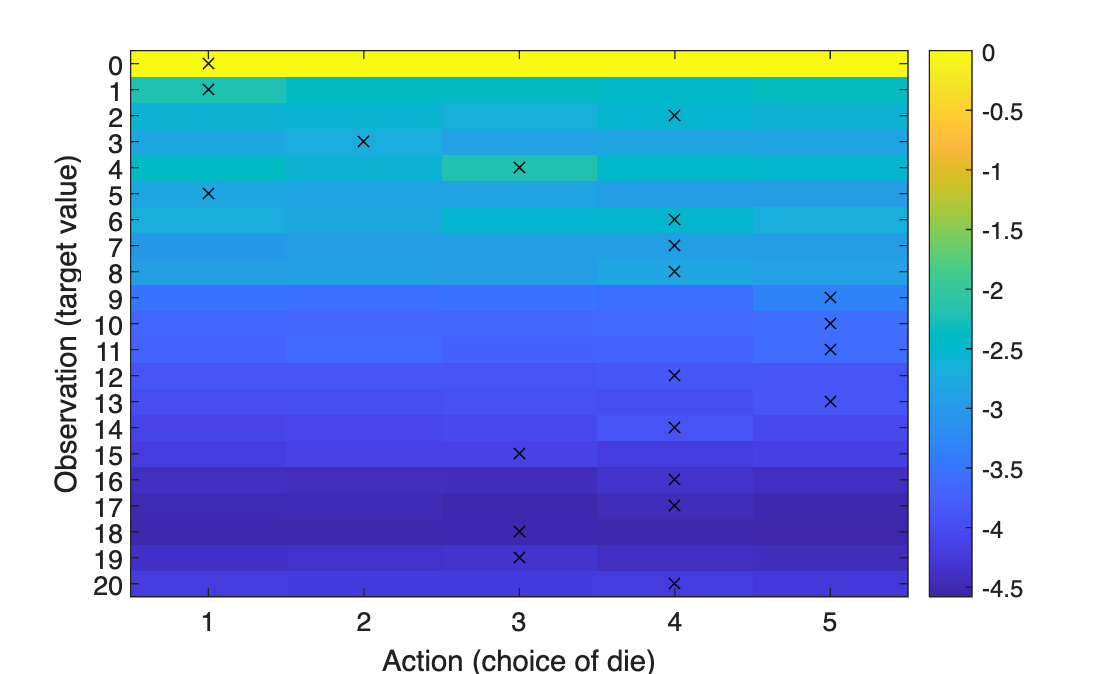

visualizeQ(trainedcritic)


[n,win]=playdice(agent,slEnv)

Target   Die       Sides       Roll
  15      2     2 2 3 3 6 6     6
   9      5     3 4 5 7 8 8     5
   4      3     1 4 4 4 5 7     4
   0      -     - - - - - -     -
Target reached in 3 steps
 
Target   Die       Sides       Roll
  10      3     1 4 4 4 5 7     4
   6      2     2 2 3 3 6 6     3
   3      2     2 2 3 3 6 6     2
   1      1     1 1 1 5 5 8     1
   0      -     - - - - - -     -
Target reached in 4 steps
 
Target   Die       Sides       Roll
  18      3     1 4 4 4 5 7     5
  13      3     1 4 4 4 5 7     4
   9      5     3 4 5 7 8 8     3
   6      2     2 2 3 3 6 6     3
   3      2     2 2 3 3 6 6     2
   1      1     1 1 1 5 5 8     1
   0      -     - - - - - -     -
Target reached in 6 steps
 
Target   Die       Sides       Roll
   1      1     1 1 1 5 5 8     1
   0      -     - - - - - -     -
Target reached in 1 steps
 
Target   Die       Sides       Roll
  17      5     3 4 5 7 8 8     4
  13      3     1 4 4 4 5 7     4
   9      5     3 4 5 7 8 8 

n =      3
     4
     6
     1
     4


win = 5×1 logical array
   1
   1
   1
   1
   1


## Evaluate the agent

Run multiple simulations.

simout = sim(agent,slEnv,rlSimulationOptions("MaxSteps",20,"NumSimulations",100))

simout = 100×1 struct array with fields:
    Observation
    Action
    Reward
    IsDone
    SimulationInfo


simout(1)

ans = struct with fields:
       Observation: [1×1 struct]
            Action: [1×1 struct]
            Reward: [1×1 timeseries]
            IsDone: [1×1 timeseries]
    SimulationInfo: [1×1 rl.storage.SimulationStorage]


Extract the reward/number of steps. Visualize the distribution.

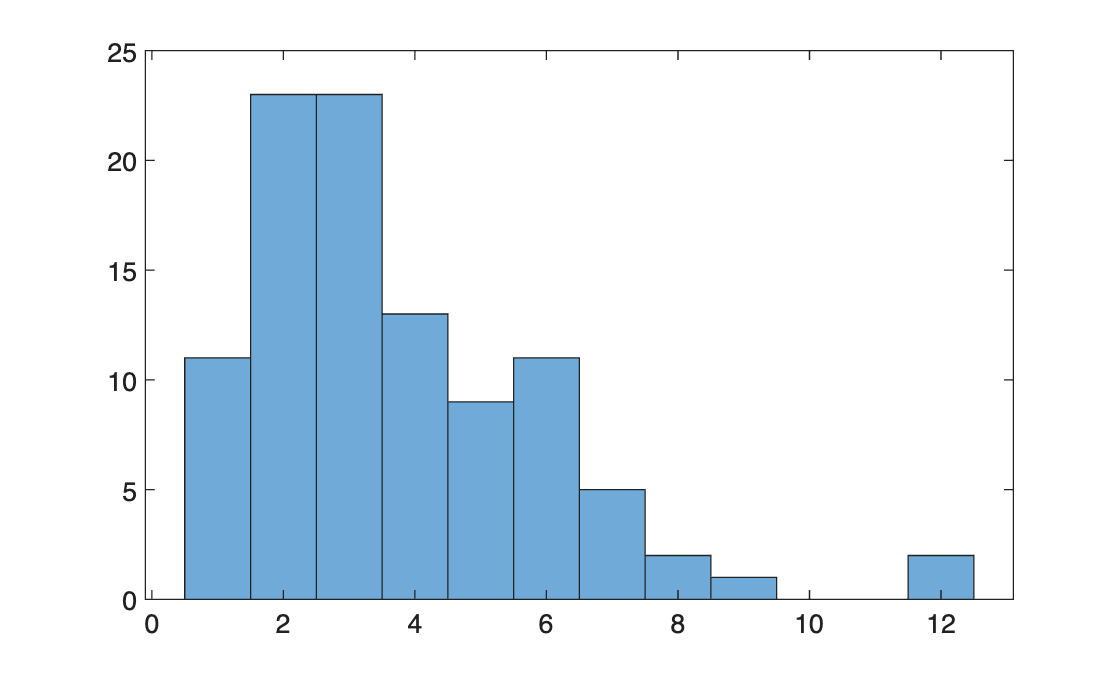

steps = arrayfun(@(x) -sum(x.Reward.Data),simout);
histogram(steps)

meansteps = mean(steps)

meansteps = 3.7300

medsteps = median(steps)

medsteps = 3

### Local functions

Randomize the random number seed in the Simulink model.

function simin = randomizeseed(simin)
simin = setVariable(simin,"seed",randi(1e5),"Workspace","targetDice");
end

Visualize the Q-table representation of an agent.

function visualizeQ(critic)
% Get possible observations and actions
o = critic.ObservationInfo.Elements;
a = critic.ActionInfo.Elements;
no = numel(o);
na = numel(a);
% Get Q value for each obs/action
Q = zeros(no,na);
for k = 1:na
    for j = 1:no
        Q(j,k) = getValue(critic,{o(j)},{a(k)});
    end
end
% Visualize result
imagesc(Q)
colorbar
xticks(1:na)
xticklabels(a)
yticks(1:no)
yticklabels(o)
xlabel("Action (choice of die)")
ylabel("Observation (target value)")
% Add policy to the plot
[~,idx] = max(Q,[],2);
hold on
plot(idx,1:no,"kx")
hold off
end